w = str2double(gedges1(:, 3))

w =    192
   154
   121
   107
    96
    91
    90
    90
    86
    86


s = gedges1(:, 1)

s = 549×1 string array
    "NED"
    "DAENERYS"
    "JON"
    "LITTLEFINGER"
    "NED"
    "DAENERYS"
    "ARYA"
    "CATELYN"
    "BRONN"
    "CERSEI"
    "CERSEI"
    "LITTLEFINGER"
    "SHAE"
    "CATELYN"
    "JOFFREY"
    "NED"
    "DAENERYS"
    "SANSA"
    "TYRION"
    "JEOR"
    "ROBB"
    "CERSEI"
    "ARYA"
    "BRAN"
    "JAIME"
    "NED"
    "BRAN"
    "LORAS"
    "CERSEI"
    "DAENERYS"


t = gedges1(:, 2)

t = 549×1 string array
    "ROBERT"
    "JORAH"
    "SAM"
    "NED"
    "VARYS"
    "DROGO"
    "NED"
    "ROBB"
    "TYRION"
    "NED"
    "ROBERT"
    "VARYS"
    "TYRION"
    "NED"
    "SANSA"
    "PYCELLE"
    "VISERYS"
    "SEPTA_MORDANE"
    "TYWIN"
    "JON"
    "THEON"
    "JOFFREY"
    "SANSA"
    "MAESTER_LUWIN"
    "NED"
    "SANSA"
    "ROBB"
    "RENLY"
    "JAIME"
    "MIRRI_MAZ_DUUR"


G= digraph(s, t, w);
E = indegree(G);
F = 2.*sqrt(E - min(E)+0.2);
colormap hsv;
p = plot(G)

p =   GraphPlot with properties:

     NodeColor: [0 0.4470 0.7410]
    MarkerSize: 2
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {}
     EdgeLabel: {}
         XData: [1×126 double]
         YData: [1×126 double]
         ZData: [1×126 double]

  Show all properties


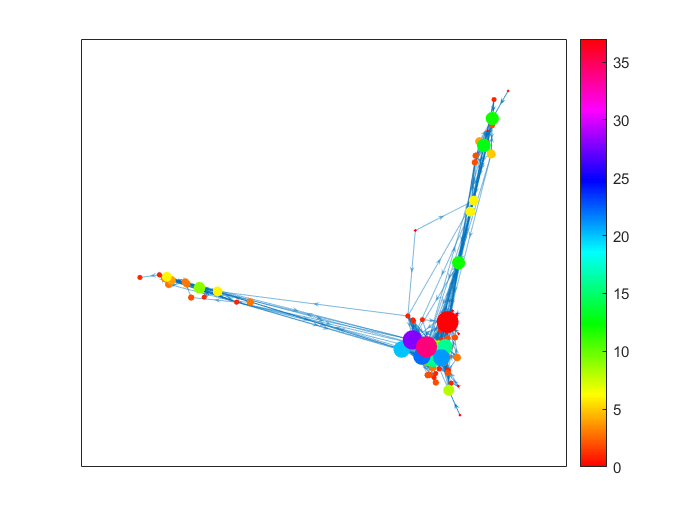

p.MarkerSize = F;
p.NodeCData = E;
colorbar

T = table(G.Nodes.Name , E)

T = 126×2 table
          Var1          Var2
    ________________    ____

    {'NED'         }     34 
    {'ROBERT'      }     28 
    {'DAENERYS'    }      1 
    {'JORAH'       }      6 
    {'JON'         }     12 
    {'SAM'         }     12 
    {'LITTLEFINGER'}     11 
    {'VARYS'       }     20 
    {'DROGO'       }      3 
    {'ARYA'        }      0 
    {'CATELYN'     }      7 
    {'ROBB'        }     21 
    {'BRONN'       }      0 
    {'TYRION'      }     37 
    {'CERSEI'      }      6 
    {'SHAE'        }      1 


T_1 = sortrows(T, "Var2", 'descend')

T_1 = 126×2 table
          Var1          Var2
    ________________    ____

    {'TYRION'      }     37 
    {'NED'         }     34 
    {'ROBERT'      }     28 
    {'SANSA'       }     22 
    {'ROBB'        }     21 
    {'VARYS'       }     20 
    {'TYWIN'       }     17 
    {'THEON'       }     16 
    {'YOREN'       }     16 
    {'PYP'         }     13 
    {'JON'         }     12 
    {'SAM'         }     12 
    {'LITTLEFINGER'}     11 
    {'RENLY'       }     11 
    {'RODRIK'      }     10 
    {'JOFFREY'     }      9 


head(T_1, 5)

ans = 5×2 table
       Var1       Var2
    __________    ____

    {'TYRION'}     37 
    {'NED'   }     34 
    {'ROBERT'}     28 
    {'SANSA' }     22 
    {'ROBB'  }     21 
